# TDE 2022 settembre 09

## Q3

clear;
clc;
syms q1 q2 q3 L real

r = [q2*cos(q1)+L*cos(q1+q3);
    q2*sin(q1)+L*sin(q1+q3);
    q1+q3];
var = [q1 q2 q3];
J = jacobian(r, var)
detJ = simplify(det(J))
qs = [q1 0 q3];

Js = subs(J, var, qs)
basis = simplify(orth(Js))
% all possible velocities are alpha * vectors of the basis

q0 = [0 0 0];
J0 = subs(J, var, q0)
basNN = simplify(null(J0))
% boh

L = 1;
qc = [pi/2; 1; 0];
syms q1(t) q2(t) q3(t)
r = [q2*cos(q1)+L*cos(q1+q3);
    q2*sin(q1)+L*sin(q1+q3);
    q1+q3];
vart = [q1; q2; q3];
J = jacobian(r, vart)
Jdot = simplify(diff(J,t))
qdot = [1, 1, -1];
qdotus = [diff(q1,t), diff(q2,t), diff(q3,t)];
% JJ = subs(J, vart, qc)
% JJdot = subs(Jdot, qdotus, qdot)

basinull = null(Js)

## Q4

clear;
clc;

q_i = pi/2;
q_f = 0;
q_dt_b = 2; % bound [rad/s] abs value
q_dtdt_b = 4; % bound [rad/s^2] abs value
V = q_dt_b;
A = q_dtdt_b;

% minimum T for rest to rest
q_dt_i =0;
q_dt_f = 0;
L = -(q_f - q_i); % abs value
Lop = V^2/A;
Top = V/A;
[T0] = MinTBCB(A, V, L) % minimum T

T0 = 1.2854

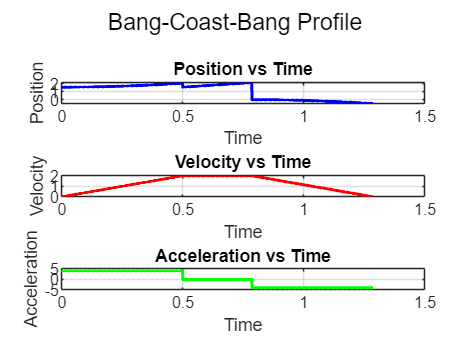

Total Time: 1.29 s
Time to accelerate: 0.50 s
Coast time: 0.29 s
Distance covered during acceleration: 0.50 m


bangCbangPlot(V, A, T0, -L, q_i, q_f)